# Pre Lab 1

Bar Yerushalmian

Ben Efrath

## Q1

% a) Double zero matrix
m1 = zeros(5,5,"double")

m1 =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0



% b) Double matrix with 0.134
m2 = zeros(5,5,"double")+double(0.134)

m2 =     0.1340    0.1340    0.1340    0.1340    0.1340
    0.1340    0.1340    0.1340    0.1340    0.1340
    0.1340    0.1340    0.1340    0.1340    0.1340
    0.1340    0.1340    0.1340    0.1340    0.1340
    0.1340    0.1340    0.1340    0.1340    0.1340



% c) Double matrix with random values [-1.5, 3.4]
% Given range [a,b] the formula: m = a + (b-a).*rand([5,5])
m3 = -1.5 + (3.4 + 1.5).*rand([5,5],"double")

m3 =     2.5465   -0.9774    2.7566    0.6139   -0.8333
    1.1379    3.2133   -1.0863    2.9622    2.7595
    3.3811   -1.4773    0.4589   -0.6089    1.3406
   -1.1169    2.2971   -0.2266   -0.2074    1.1943
    0.6691    2.5048    2.4203   -0.7869   -0.7897



% d) Make m3 into uint8 with casting.
% All the negative numbers turned to 0. All fractions were rounded to the
% closest integer. Becasue it's unsigned, it did meet our expectations.
m3 = uint8(m3)

m3 = 5×5 uint8 matrix
   3   0   3   1   0
   1   3   0   3   3
   3   0   0   0   1
   0   2   0   0   1
   1   3   2   0   0



% e) Make 5x5 matrix using uint8 in range of [0,250]
A = uint8(250.*rand([5,5]))

A = 5×5 uint8 matrix
   213    19   104   122   195
   156    60    12    84    97
    88    31   226   225    60
   128    46   236    92   101
   100    60   123    28    24



% f) 
% All The values above 127 are now 255.
A = A.*2

A = 5×5 uint8 matrix
   255    38   208   244   255
   255   120    24   168   194
   176    62   255   255   120
   255    92   255   184   202
   200   120   246    56    48



% g)
% Find the maximum value in the matrix using find().
v = max(A(:))           % value

v = uint8
255

[row,column] = find(A == v)

row =      1
     2
     4
     3
     4
     3
     1


column =      1
     1
     1
     3
     3
     4
     5


## Q2

% a)
% Create unit matrix I1.
I1=eye(3,4,"double")

I1 =      1     0     0     0
     0     1     0     0
     0     0     1     0



% b)
% Create row index matrix I2 and column index matrix I3.
x = 1:4;
y = 1:3;
[I3,I2] = meshgrid(x,y)

I3 =      1     2     3     4
     1     2     3     4
     1     2     3     4


I2 =      1     1     1     1
     2     2     2     2
     3     3     3     3



% c)
% Transform I3 matrix into a vector.
% The function sets the columns of the 
% matrix one after eachother to creare a vector.
I3a = reshape(I3,1,[])

I3a =      1     1     1     2     2     2     3     3     3     4     4     4



% d)
% We didnt get the same vector. This Vector is like reshape of I2.
% Because we transposed I3 it became I2
% Now it's like the rows are set one after eachother to create a vector.
I3b = reshape(I3.',1,[])

I3b =      1     2     3     4     1     2     3     4     1     2     3     4



% e)
% the vector I3c is similar to the vector I3a.
% we can say that reshape makes a column vector from the matrix and than
% transpose it.
I3c = I3(:).'

I3c =      1     1     1     2     2     2     3     3     3     4     4     4


## Q3

% repmat Is copying the matrix 3 times in the x axes and 2 times in the y
% axes.
A1 = repmat(A,3,4)

A1 = 15×20 uint8 matrix
   255    38   208   244   255   255    38   208   244   255   255    38   208   244   255   255    38   208   244   255
   255   120    24   168   194   255   120    24   168   194   255   120    24   168   194   255   120    24   168   194
   176    62   255   255   120   176    62   255   255   120   176    62   255   255   120   176    62   255   255   120
   255    92   255   184   202   255    92   255   184   202   255    92   255   184   202   255    92   255   184   202
   200   120   246    56    48   200   120   246    56    48   200   120   246    56    48   200   120   246    56    48
   255    38   208   244   255   255    38   208   244   255   255    38   208   244   255   255    38   208   244   255
   255   120    24   168   194   255   120    24   168   194   255   120    24   168   194   255   120    24   168   194
   176    62   255   255   120   176    62   255   255   120   176    62   255   255   120   176    62   255   255   120
   255  

## Q4

% flipud flips the matrix upside down.
A=flipud(A)

A = 5×5 uint8 matrix
   200   120   246    56    48
   255    92   255   184   202
   176    62   255   255   120
   255   120    24   168   194
   255    38   208   244   255


## Q5

% 1st Ex
A1 = [ 1 2 3 4 ]

A1 =      1     2     3     4



B1_pre = padarray(A1,3,9,'pre')

B1_pre =      9     9     9     9
     9     9     9     9
     9     9     9     9
     1     2     3     4



% 2nd Ex
A2 = [ 1 2; 3 4 ]

A2 =      1     2
     3     4



B2_post = padarray(A2,[3 2],'replicate','post')

B2_post =      1     2     2     2
     3     4     4     4
     3     4     4     4
     3     4     4     4
     3     4     4     4



% 1st one with 'post' and 'both'

B1_post = padarray(A1,3,9,'post')

B1_post =      1     2     3     4
     9     9     9     9
     9     9     9     9
     9     9     9     9



B1_both = padarray(A1,3,9,'both')

B1_both =      9     9     9     9
     9     9     9     9
     9     9     9     9
     1     2     3     4
     9     9     9     9
     9     9     9     9
     9     9     9     9



% 2nd one with 'both' and 'circular'

B2_both = padarray(A2,[3 2],'circular','both')

B2_both =      3     4     3     4     3     4
     1     2     1     2     1     2
     3     4     3     4     3     4
     1     2     1     2     1     2
     3     4     3     4     3     4
     1     2     1     2     1     2
     3     4     3     4     3     4
     1     2     1     2     1     2



% padarray is taking an array and padding it with a given number or a
% series of numbers. It's done with additional collums or rows. There is an
% option to choose where to pad it.

## Q6

% imshow show the matrix as an image where every number in the matrix
% represent a level of gray, the square brackets are the range for the gray level.
% it means that 10 is black and 20 is white.
I = uint8(20.*rand([3,5]))

I = 3×5 uint8 matrix
    3   12    7    1   15
   19    1   16    3   13
   19    5    0   13    9


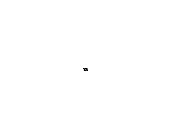

imshow(I ,[10 20])

## Q7

% what?

Error using rgb2gray>parse_inputs
MAP must be a m x 3 array. Use im2gray for RGB and grayscale images.

Error in rgb2gray (line 51)
isRGB = parse_inputs(X);

## Q8

%ImgLoad(D:\עיבוד תמונה\lab 1,barbara_gray.raw,1024,256)

Invalid use of operator.